clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;


r1=[-0.000;3.580;2.395];
u31=[0;0;1];
r2=[3.100;1.790;7.185];
u32=[0;0;1];
r3=[-3.100;8.949;2.395];
u33=[0;0;1];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];

hold on 
axis([0 15 0 15]);
for R1=9:-0.3:3.3 %离心率
    R3=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     9.0000    2.4000    1.0354


ans =     8.7000    2.4000    1.0382


ans =     8.4000    2.4500    1.0010


ans =     8.1000    2.4500    1.0044


ans =     7.8000    2.4500    1.0083


ans =     7.5000    2.4500    1.0126


ans =     7.2000    2.4500    1.0174


ans =     6.9000    2.4500    1.0229


ans =     6.6000    2.4500    1.0291


ans =     6.3000    2.4500    1.0363


ans =     6.0000    2.5000    1.0068


ans =     5.7000    2.5000    1.0164


ans =     5.4000    2.5000    1.0276


ans =     5.1000    2.5500    1.0053


ans =     4.8000    2.5500    1.0212


ans =     4.5000    2.6000    1.0067


ans =     4.2000    2.6000    1.0301


ans =     3.9000    2.6500    1.0274


ans =     3.6000    2.7500    1.0057


ans =     3.3000    2.8500    1.0004



for R3=3:0.3:9 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     2.9500    3.0000    1.0055


ans =     2.6000    3.3000    1.0006


ans =     2.3500    3.6000    1.0227


ans =     2.2500    3.9000    1.0099


ans =     2.1500    4.2000    1.0182


ans =     2.1000    4.5000    1.0097


ans =     2.0500    4.8000    1.0112


ans =     2.0000    5.1000    1.0214


ans =     1.9500    5.4000    1.0392


ans =     1.9500    5.7000    1.0190


ans =     1.9500    6.0000    1.0018


ans =     1.9000    6.3000    1.0319


ans =     1.9000    6.6000    1.0191


ans =     1.9000    6.9000    1.0079


ans =     1.8500    7.2000    1.0467


ans =     1.8500    7.5000    1.0380


ans =     1.8500    7.8000    1.0303


ans =     1.8500    8.1000    1.0234


ans =     1.8500    8.4000    1.0173


ans =     1.8500    8.7000    1.0118


ans =     1.8500    9.0000    1.0068




for R3=2:0.3:10 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     3.0500    2.0000    1.0330


ans =     3.0500    2.3000    1.0330


ans =     3.0500    2.6000    1.0330


ans =     3.0500    2.9000    1.0330


ans =     3.0500    3.2000    1.0330


ans =     3.0500    3.5000    1.0330


ans =     3.0500    3.8000    1.0330


ans =     3.0500    4.1000    1.0330


ans =     3.0500    4.4000    1.0330


ans = 1×3
    3.0500    4.7000    1.0330


ans = 1×3
    3.0500    5.0000    1.0330


ans = 1×3
    3.0500    5.3000    1.0330


ans = 1×3
    3.0500    5.6000    1.0330


ans = 1×3
    3.0500    5.9000    1.0330


ans = 1×3
    3.0500    6.2000    1.0330


ans = 1×3
    3.0500    6.5000    1.0330


ans = 1×3
    3.0500    6.8000    1.0330


ans = 1×3
    3.0500    7.1000    1.0330


ans = 1×3
    3.0500    7.4000    1.0330


ans = 1×3
    3.0500    7.7000    1.0330


ans = 1×3
    3.0500    8.0000    1.0330


ans = 1×3
    3.0500    8.3000    1.0330


ans = 1×3
    3.0500    8.6000    1.0330


ans = 1×3
    3.0500    8.9000    1.0330


ans = 1×3
    3.0500    9.2000    1.0330


ans = 1×3
    3.0500    9.5000    1.0330


ans = 1×3
    3.0500    9.8000    1.0330


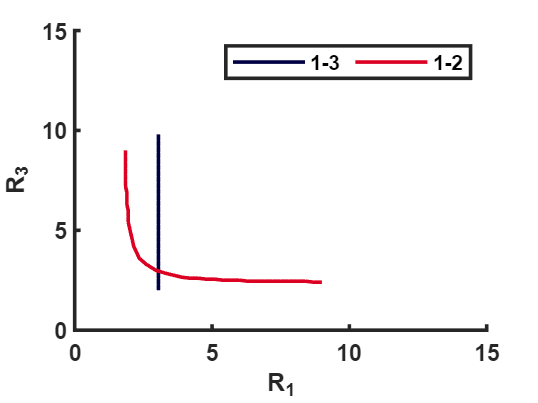


plot(x2,y2,'color',[0, 0, 69]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-3');

plot(x1,y1,'color',[221, 0, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-2');







set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

